% формирование массива данных из листов с ГИС и суммы ГРС для аппроксимации запаса
d = dir('C:\Users\user\MATLAB Drive\1Exponenta\27.02_zapas\data_zapas_all_chetnie_chasi_moll_grunti');
d(1:3) = []; %создание пустого массива
t_f_g = [];

for i = 1:numel(d)
    disp(i)% демо считывания данных по месяцам
    str = d(i).folder +"\"+ d(i).name; %считываем имя файла в директории d
    [a,txt] = readfile_all(str); % читаем файл, к которому обращаемся
    t_f_g = [t_f_g; [a(:,:)]];
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11



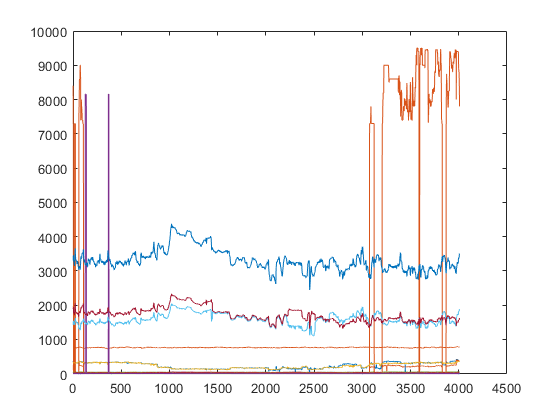

plot(t_f_g);

save zapas_formula_grunti t_f_g

function [t_f_g,txt] = readfile_all(str)
[t_f_g,txt] = xlsread(str,'КС, МГ');
s = all(isnan(t_f_g));
t_f_g(:,s) = [];
b = all(isnan(t_f_g),2);
t_f_g(b,:) = [];
end